## **Team Remix Project**

**Joe Evans, Maxine Khumalo, Lang Liu**

**Yee Algorithm**

This code is modified and built-on from research work that Evans did in the Fall of 2020.

## Version Comments

    I introduced a square wave in space to see what would happen to the propogation.  @ S=1/2.

## Admin

clearvars

sympref('FloatingPointOutput',true);

## Section 1: Define Constants and Courant Number

## Given Constants

e0 = 8.86e-12; %permittivity of free space (F/m)

mu0 = 4e-7 .* pi; % permeability of free space (H/m)

er = 1; %permittivity in medium (set to 1 for free space)

mur = 1; %permeability in medium (set to 1 for free space)

e = er .* e0; % e = epsilon (Units F/m)

mu = mur .* mu0; % (Units: H/m)

c = 1./(sqrt(e0*mu0));

Set Courant number (S)

Set $S=\frac{c \Delta t}{\Delta z}$

Then $\Delta t = S\frac{\Delta z}{c}$

S = 0.5; %Courant Number of 1/2 corresponds to the magic time step

c = 3e8; % speed of light in (meters / second)

dz = 5e-3; %space increment in meters as defined in the project part 3 parameters

dt = S .* (dz./c) ;


## Section 2: Set up the Wave

Gaussian Pulse "Wave Packet"

sigma = 8 .* dt;  %as defined in Project Part 3

ts = 20 .* dt;

E0 = 1;

Es = @(t) E0 .* exp(-((t-ts)^2)./(sigma^2));




Create Matrices to hold wave values



L = 1./dz;               %Number of Space Positions so that z(L) = 1

Tmax = 6 .* sigma;          
T = Tmax ./ dt;           %Number of Time Steps so that over 99% of the Guassian pulse is complete

%Matrices to hold E and H values will be row vectors of length 2L, so that
%each position represents a half step.  

E = zeros(1,2.*L);          %Matrix of electric field values in space (@ t)
Ein = zeros(1,2.*L);        %Temporary Placeholder for the E value input for each space step
Eout = zeros(1,2.*L);       %Temproary placeholder for the E value output for each space step

H = zeros (1,2.*L);         %Matrix of magnetic field values in space (@ t)
Hin = zeros(1,2.*L);        %Temporary placeholder for the H value input for each space step
Hout = zeros (1,2.*L);      %Temporary placeholder for the H value output for each space step

zs = L./4;                  %Define the space point of the Gaussian pulse


Guassian

This is a Guassian in space for the E field, which has been introduced in lieu of a Guassian pulse in time for the moment.  

  Z=(dz/2):(dz/2):1;
%  a = 1;     %height
%  b = 1/4;    %center
%  d = 8*dz;    %width
%  f=@(x)a*exp(-((x-b).^2)/(d^2));
%  E(:)=f(Z);
% 


Square Wave

I make use of this square wave to test my code to see if it is truly at the magic time step

E(50:150)=1;

## Section 3: Setup Video

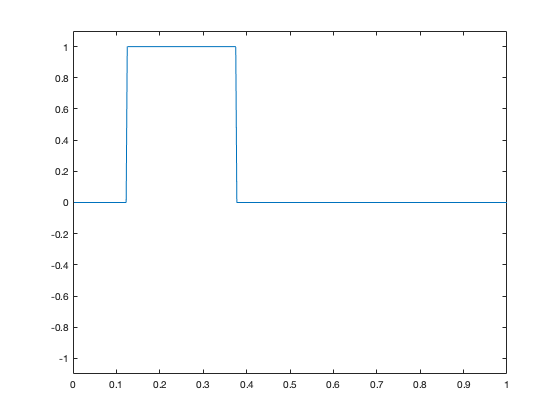

v=VideoWriter("Wave","MPEG-4");
open(v)
plot(Z,E(:))
xlim([0 1]);
ylim([-1.1 1.1]);
Ylabel="Amplitude";
Xlabel="z";
axis manual
set(gca,"nextplot","replacechildren")
frame=getframe(gcf);

writeVideo(v,frame)


## Section 4: Time step the wave using the Yee Algorithm


for t=1:T                              %Iterate for T total time steps

    
%%%%%%%%%%%%%%%%%%%%% Calculate the E Field %%%%%%%%%%%%%%%%%%%
   
%     E(1) = H(2);                          % ABCs 
%     E(S) = H(S);
    
        for k=2:(2*L-1)                     
        Hout(k) = H(k+1);
        Hin(k)= H(k-1);
        end   
        
        for k=2:(2*L-1)
        E(k) =  E(k) - ( S ./ er )  .* ( Hout(k) - Hin(k) );    %calculate E 
        end

%%%%%%%%%%%%%%%%%%% Introduce next E pulse Value %%%%%%%%%%%%%%%%%%

                      
    %E(2*zs) = Es(t*dt); %Calculate the next value of the pulse at z = zs 

   
   
%%%%%%%%%%%%%%%%%% Calculate H Field %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
%     H(1) = E(1);                          % ABCs 
%     H(S) = E(S-1);
    
    for k=2:(2*L-2)                       
        Eout(k) = E(k+2);
        Ein(k) = E(k);                % these values are populated with E @ t+(1/2)
        
    end
    
    for k=2:(2*L-1)
        
        H(k+1) = H(k+1) - (S ./ mur ) .* ( Eout(k) - Ein(k) );   %calculate H
        
    end
    
%%%%%%%%%%%%%%%%% Plot and Write frame to video %%%%%%%%%%%%%%%%%%%%

    plot(Z,E(:));
    frame=getframe(gcf);
    pause(0.5)
    writeVideo(v,frame)
    
end

close(v)